# Gabriel Colangelo Homework 4

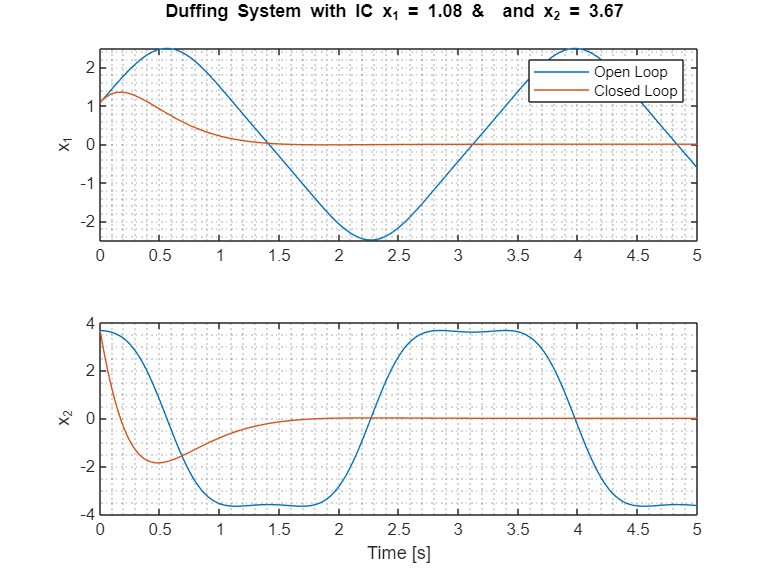

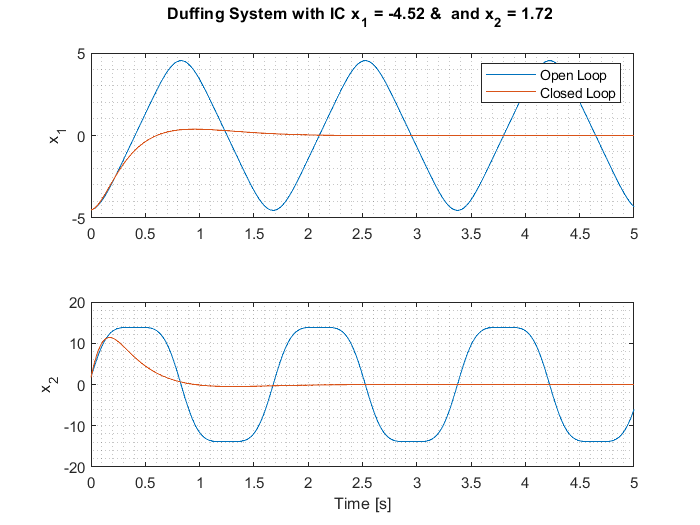

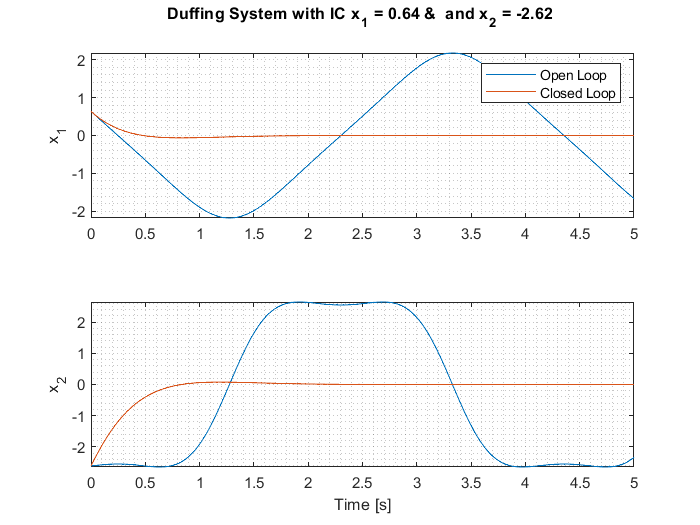

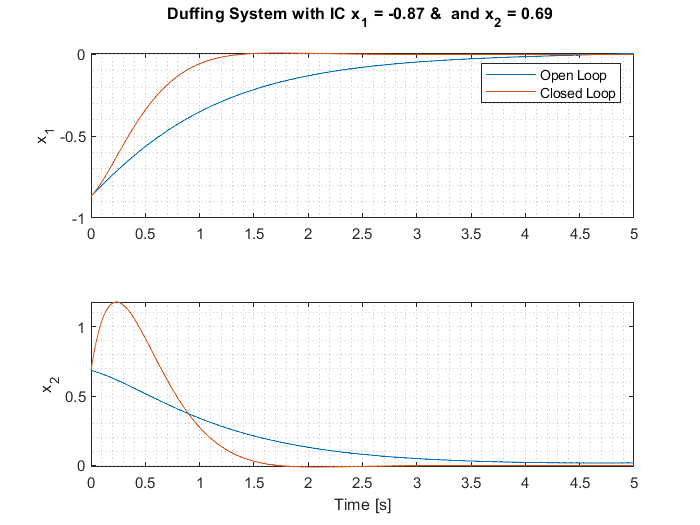

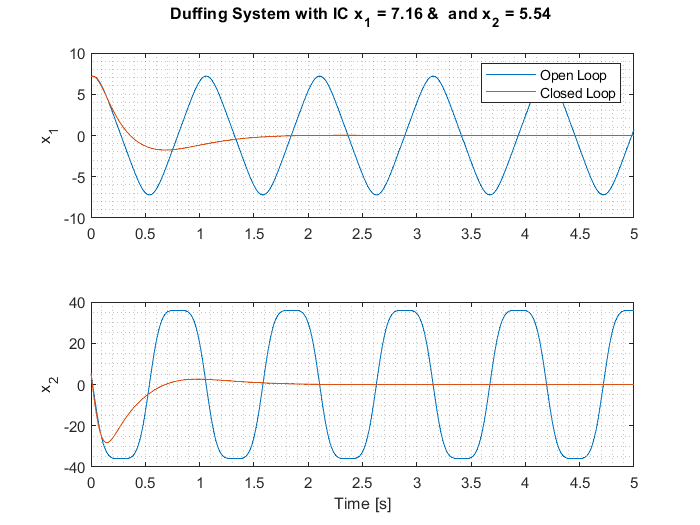

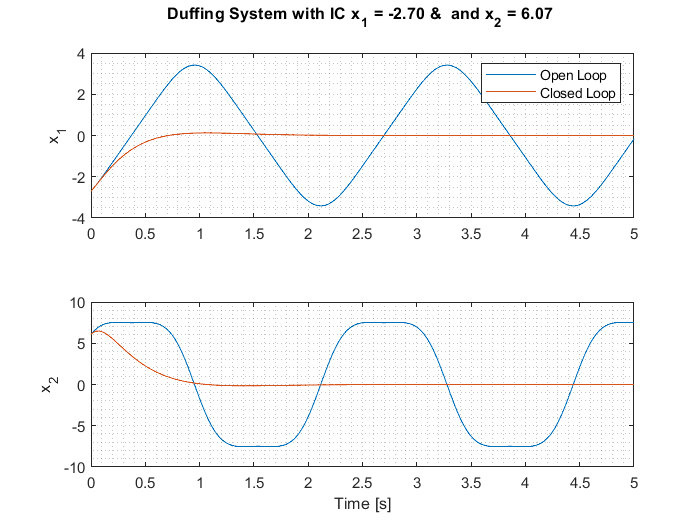

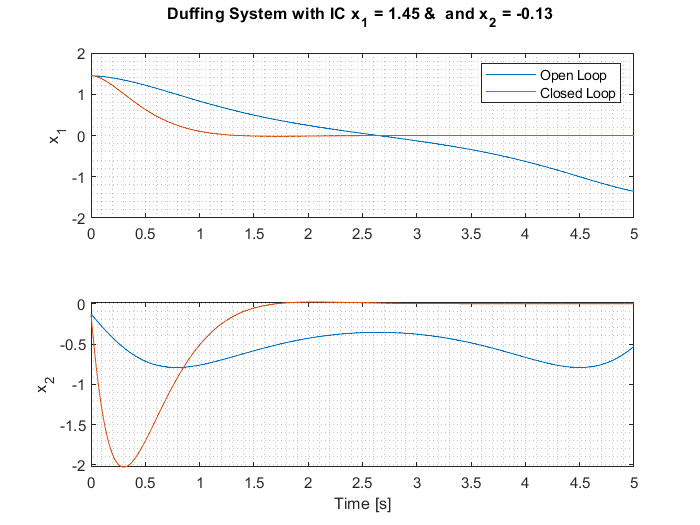

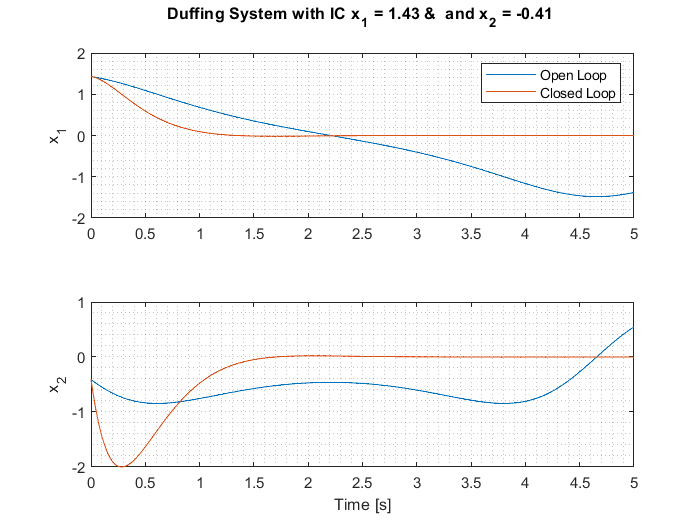

clear
close all
clc

% Control gains 
k1      = 10;   % From Lyapunov analysis k1 > 1
k2      = 5;    % From Lyapunov analysis k2 > 0

% Initial conditions 
IC      = zeros(2,1) + 2*randn(2,10);

% sim time
time    = (0:.005:5)';

% ODE45 solver options
options = odeset('AbsTol',1e-8,'RelTol',1e-8);

% Loop through all IC's
for i = 1:length(IC)
    % Open loop system
    [~, X_open]   = ode45(@(t,x) DuffingSystem(t,x), time, IC(:,i), options);

    % Closed loop system
    [~, X_cl]     = ode45(@(t,x) ControlledDuffingSystem(t,x,[k1 k2]),...
                    time, IC(:,i), options);

    % Generate Plots
    title_str     = sprintf(['Duffing System with IC x_1 = %.2f & ',...
                            ' and x_2 = %.2f \n'],IC(1,i),IC(2,i));

    figure(i)
    subplot(211)
    plot(time,X_open(:,1), time, X_cl(:,1))
    ylabel('x_1')
    grid minor
    legend('Open Loop','Closed Loop')
    title(title_str)
    subplot(212)
    plot(time,X_open(:,2), time, X_cl(:,2))
    ylabel('x_2')
    grid minor
    xlabel('Time [s]')

end

function xdot = DuffingSystem(t,x)
    % State space model
    xdot(1,1)   = x(2,1);
    xdot(2,1)   = x(1,1) - x(1,1)^3;
end

function xdot = ControlledDuffingSystem(t,x,K)
    % Control law, u = -k1*x1 - k2*x2
    u           = -K*x;

    % State space model
    xdot(1,1)   = x(2,1);
    xdot(2,1)   = x(1,1) - x(1,1)^3 + u;
end